# PPO Agent Building for Water Tank Example

open_system("rlwatertank_discretePPO");

## Environment Definition

actInfo = rlFiniteSetSpec([0 1 2 5 10], Name="additional flow rate");

obsInfo = rlNumericSpec([3 1],...
    LowerLimit=[-inf -inf 0  ]',...
    UpperLimit=[ inf  inf inf]');
obsInfo.Name = "observations";
obsInfo.Description = "integrated error, error, and measured height";

env = rlSimulinkEnv("rlwatertank_discretePPO", ...
        "rlwatertank_discretePPO/RL Agent", ...
        obsInfo, actInfo);
env.ResetFcn = @(in)localResetFcn(in);

Ts = 1; % Sampling time = 1s
Tf = 512; % Max steps (s) = 1 hour
rng(0);

## Define the PPO Agent's Actor

actorNetLayers = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(20)
    reluLayer("Name", "reluActivation")
    fullyConnectedLayer(length(actInfo.Elements))
    softmaxLayer("Name", "output")
];
actorNet = dlnetwork(actorNetLayers);
summary(actorNet)

   Initialized: true

   Number of learnables: 185

   Inputs:
      1   'input'   3 features



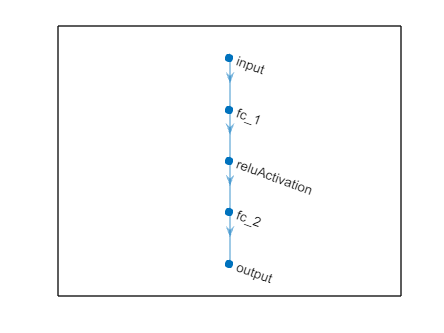


figure;
plot(actorNet);


actor = rlDiscreteCategoricalActor(actorNet, obsInfo, actInfo, UseDevice="gpu");

## Define the PPO Agent's Critic

Contrary to DDPG, a PPO's critic is a value function that only depends on the current state, i.e., $V(s_i)$ and returns a single scalar.

criticNetLayers = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(60)
    reluLayer("Name", "reluActivation")
    fullyConnectedLayer(1)
];

criticNet = dlnetwork(criticNetLayers);
summary(criticNet)

   Initialized: true

   Number of learnables: 301

   Inputs:
      1   'input'   3 features



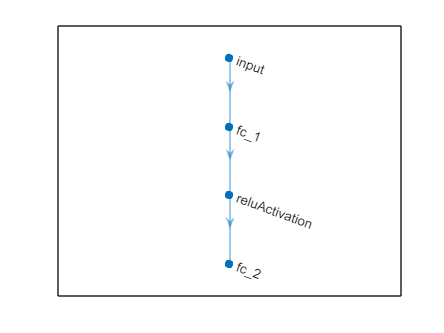


figure;
plot(criticNet);


critic = rlValueFunction(criticNet, obsInfo, UseDevice="gpu");

## Create the PPO Agent

agentOpts = rlPPOAgentOptions(...
    SampleTime = Ts,...
    ExperienceHorizon = ceil(Tf/Ts),... % Only train after each episode
    DiscountFactor = 0.99,...
    MiniBatchSize = 64,...
    NumEpoch = 4,...
    ClipFactor = 0.02,...
    GAEFactor = 0.95);

agent = rlPPOAgent(actor, critic, agentOpts);

% agent.AgentOptions.LearningFrequency = 128;

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-4;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-4;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

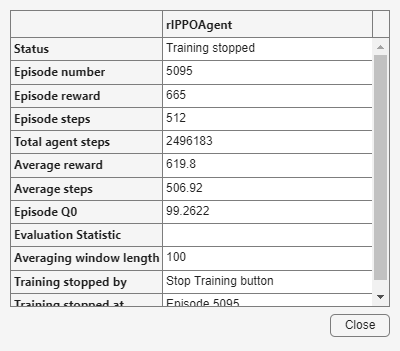

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=3000);

trainingStats = train(agent, env, trainOpts);

## Validate after the training

rng(2);
simOpts = rlSimulationOptions(MaxSteps=100, StopOnError="on");
experiences = sim(env, agent, simOpts);

## Local Reset Function

function in = localResetFcn(in)
    % Randomize reference signal
    blk = sprintf("rlwatertank_discretePPO/Desired \nWater Level");
    h = 3*randn + 10;
    while h <= 0 || h >= 20
        h = 3*randn + 10;
    end
    in = setBlockParameter(in,blk,Value=num2str(h));
    
    % Randomize initial height
    h = 3*randn + 10;
    while h <= 0 || h >= 20
        h = 3*randn + 10;
    end
    blk = "rlwatertank_discretePPO/Water-Tank System/H";
    in = setBlockParameter(in,blk,InitialCondition=num2str(h));
end